# Train a Feed Forward Neural Network using Parareal algorithm

We first deal with the already tested classification task, from the paper "*Deep Learning: An Introduction for Applied Mathematicians*".

clear all; close all; clc;
addpath("parareal_systems\")

### Setup dataset and network

Set up the dataset divided into two classes

x1 = [0.1,0.3,0.1,0.6,0.4];
y1 = [0.1,0.4,0.5,0.9,0.2];

x2 = [0.6,0.5,0.9,0.4,0.7];
y2 = [0.3,0.6,0.2,0.4,0.6];

x = [x1, x2; y1, y2];
y = [ones(1,5) zeros(1,5); zeros(1,5) ones(1,5)];

Set up network hyperparameters

sigma = @(t) 1./(1+exp(-t));
sigmaprime = @(t) sigma(t).*(1-sigma(t));
shape = [2, 3, 3, 2];
niter = 7e4;
eta = 0.05;

### Train the network

Train with Parareal / ode45

%% Our problem is here. 
disp('begin')

begin


tic
[W_, b_] = TrainNetworkParareal( ...
        x, y, niter, eta, sigma, sigmaprime, shape);

T=3500
iteration 1/50
iteration 2/50
iteration 3/50
iteration 4/50
iteration 5/50
iteration 6/50
iteration 7/50
iteration 8/50
iteration 9/50
iteration 10/50
iteration 11/50
iteration 12/50
iteration 13/50
iteration 14/50
iteration 15/50
iteration 16/50
iteration 17/50
iteration 18/50
iteration 19/50
iteration 20/50
iteration 21/50
iteration 22/50
iteration 23/50
iteration 24/50
iteration 25/50
iteration 26/50
iteration 27/50
iteration 28/50
iteration 29/50
iteration 30/50
iteration 31/50
iteration 32/50
iteration 33/50
iteration 34/50
iteration 35/50
iteration 36/50
iteration 37/50
iteration 38/50
iteration 39/50
iteration 40/50
iteration 41/50
iteration 42/50
iteration 43/50
iteration 44/50
iteration 45/50
iteration 46/50
iteration 47/50
iteration 48/50
iteration 49/50
iteration 50/50


training_time_parareal = toc

training_time_parareal = 398.6807

disp('end')

end


Load wheights and biases of the network trained with plain Gradient Descent for a comparison

load reference.mat
normsw = [];
normsb = [];
for l = 1:numel(shape)-1
    normsw = [normsw, norm(W{l}-W_{l},2)];
    normsb = [normsb, norm(b{l}-b_{l},2)];
end
disp('Norms of wheight matrices: ')

Norms of wheight matrices: 


disp(normsw)

   13.0576   12.2237   14.8289



disp('Norms of bias vectors: ')

Norms of bias vectors: 


disp(normsb)

    4.1356    4.8437    4.9069



### Display what the network has learned

Generate random data in the square [0,1]^2

n = 300;
testDatax = rand(n, 2);

Predict classes and display new data using the previously trained network (reference)

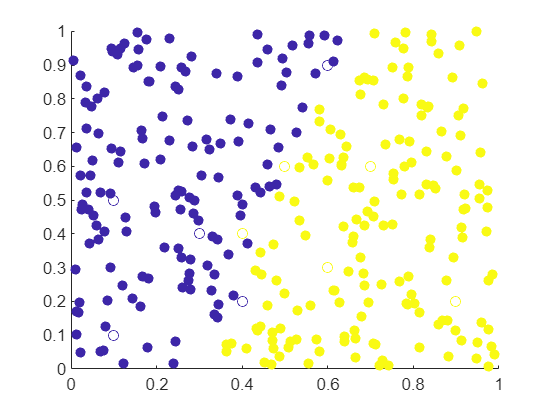

testDatay = PredictClasses(W, b, sigma, testDatax');

x = x';
y = int32([zeros(5, 1); ones(5, 1)]');
figure
scatter(x(:,1), x(:,2), [], y, 'o');
hold on;
scatter(testDatax(:,1), testDatax(:,2), [], testDatay, 'filled');

Predict classes and display new data using the network trained with Parareal

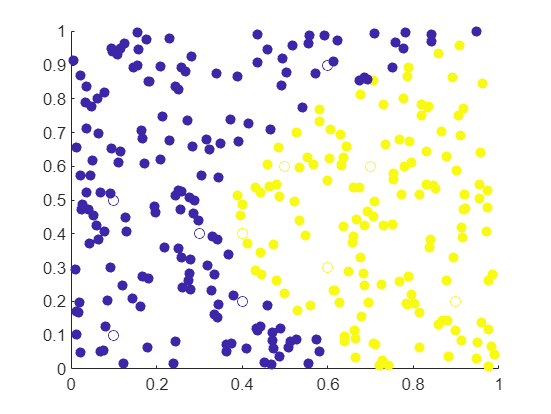

testDatay = PredictClasses(W_, b_, sigma, testDatax');
y = int32([zeros(5, 1); ones(5, 1)]');
figure
scatter(x(:,1), x(:,2), [], y, 'o');
hold on;
scatter(testDatax(:,1), testDatax(:,2), [], testDatay, 'filled');